# maoyang / 206221321 —— 第一周任务三：含充放电互斥约束的配电网日前优化调度（MISOCP）

clearvars; close all; clc;
Stu_ID = '206221321';
XY = mod(str2double(Stu_ID), 100);
X_digit = floor(XY / 10);
alpha_personal = 1 + 0.002 * XY;
case_name = 'case_nongcun';
ess_buses = [4 9 14];          
pv_buses = ess_buses;
dt = 1;

## 路径与课程数据

script_dir = fileparts(mfilename('fullpath'));
if isempty(script_dir), script_dir = pwd; end
addpath(fullfile(script_dir,'helpers'));
ess_week1_setup(script_dir);
case_dir = fullfile(script_dir,'data');
profiles = load(fullfile(case_dir, 'profiles_24h.mat'));
mpc = loadcase(case_name);
T = double(profiles.T);
assert(T == 24, '本任务需要24个时段。');
out_dir = fullfile(script_dir, 'day3_results');
if ~isfolder(out_dir), mkdir(out_dir); end

## 任务三场景参数（课程给定，与学号无关）

Sbase = mpc.baseMVA;
N_bus = size(mpc.bus, 1);
N_br = size(mpc.branch, 1);
N_ess = numel(ess_buses);
N_pv = numel(pv_buses);
fbus = mpc.branch(:, 1);
tbus = mpc.branch(:, 2);
r_br = mpc.branch(:, 3);
x_br = mpc.branch(:, 4);
P_ess_rated_MW = 1.5;
P_pv_rated_MW = 1.2;
E_ess_rated_MWh = 3.0;     
eta_ch = 0.90;
eta_dis = 0.95;
SoC_min = 0.20;
SoC_max = 0.80;
SoC_0 = 0.50;
V_min = 0.95;
V_max = 1.05;

Pd_pu = (mpc.bus(:, 3) * alpha_personal / Sbase) * profiles.load_curve_pu';
Qd_pu = (mpc.bus(:, 4) * alpha_personal / Sbase) * profiles.load_curve_pu';
P_pv_max_pu = (P_pv_rated_MW / Sbase) * repmat(profiles.pv_curve_pu', N_pv, 1);
P_ess_rated_pu = P_ess_rated_MW / Sbase;
E_ess_rated_pu = E_ess_rated_MWh / Sbase;
price_MWh = profiles.price_MWh(:);

Params = struct('Sbase', Sbase, 'T', T, 'dt', dt, 'N_bus', N_bus, 'N_br', N_br, ...
    'N_ess', N_ess, 'N_pv', N_pv, 'fbus', fbus, 'tbus', tbus, 'r_br', r_br, 'x_br', x_br, ...
    'ess_buses', ess_buses, 'pv_buses', pv_buses, 'Pd_pu', Pd_pu, 'Qd_pu', Qd_pu, ...
    'P_pv_max_pu', P_pv_max_pu, 'P_ess_rated_pu', P_ess_rated_pu, ...
    'E_ess_rated_pu', E_ess_rated_pu, 'eta_ch', eta_ch, 'eta_dis', eta_dis, ...
    'SoC_min', SoC_min, 'SoC_max', SoC_max, 'SoC_0', SoC_0, 'V_min', V_min, 'V_max', V_max, ...
    'price_MWh', price_MWh, 'alpha', alpha_personal);

fprintf('==== maoyang / %s 第一周任务三：配电网日前 MISOCP 调度 ====\n', Stu_ID);

==== maoyang / 206221321 第一周任务三：配电网日前 MISOCP 调度 ====


fprintf('算例 %s（%d 节点 / %d 支路）| alpha = %.4f | 光伏 %.1f MW×%d | 储能 %.1f MW / %.1f MWh×%d\n', ...
    case_name, N_bus, N_br, alpha_personal, P_pv_rated_MW, N_pv, ...
    P_ess_rated_MW, E_ess_rated_MWh, N_ess);

算例 case_nongcun（49 节点 / 48 支路）| alpha = 1.0420 | 光伏 1.2 MW×3 | 储能 1.5 MW / 3.0 MWh×3




local_solver = 'MATLAB coneprog + intlinprog';

## 三个目标依次求解并校核

objectives = {'A', 'B', 'C'};
objective_names = {'最大化光伏消纳', '最小化全天网损', '最小化购电成本'};
Day3 = struct('StudentID', Stu_ID, 'Case', case_name, 'Alpha', alpha_personal, ...
    'PVNodes', pv_buses, 'ESSNodes', ess_buses, 'PVRated_MW', P_pv_rated_MW, ...
    'PowerRating_MW', P_ess_rated_MW, 'EnergyRating_MWh', E_ess_rated_MWh, ...
    'SoC0', SoC_0, 'SoCmin', SoC_min, 'SoCmax', SoC_max, ...
    'EtaCharge', eta_ch, 'EtaDischarge', eta_dis, 'TimeStep_h', dt, ...
    'AssignedObjective', 'A', 'Solver', local_solver, ...
    'Price_YuanPerMWh', price_MWh, 'TimeSeries', struct());

Comparison = table('Size', [numel(objectives) 11], 'VariableTypes', ...
    {'string', 'string', 'string', 'double', 'double', 'double', 'double', ...
    'double', 'double', 'double', 'double'}, ...
    'VariableNames', {'Objective', 'Description', 'Solver', 'Curtailment_MWh', ...
    'LineLoss_MWh', 'GridCost_Yuan', 'MaxConeGap', 'SimultaneousPower_MW', ...
    'MinACVoltage', 'MaxACVoltage', 'ACVoltageError_pu'});

for k = 1:numel(objectives)
    obj_letter = objectives{k};
    fprintf('\n---- 目标 %s：%s ----\n', obj_letter, objective_names{k});
    [Dispatch, SolverName, SolveSeconds, ObjValue] = solve_dispatch(mpc, Params, obj_letter, ...
        local_solver);
    [Dispatch, NetObjective] = finish_network(Dispatch, Params, obj_letter);
    Data = pack_check_data(Dispatch, mpc, Params, Stu_ID, case_name, obj_letter, ...
        SolverName, SolveSeconds);
    [Report, V_ac] = ess_live_check_dispatch(Data);
    Report.Curtailment_MWh = max(0, Report.Curtailment_MWh);
    Report.ObjectiveValue = ObjValue;
    Report.NetworkObjective = NetObjective;
    Report.LowerBound = Dispatch.LowerBound;
    Report.UpperBound = Dispatch.UpperBound;
    Report.RelativeOptimalityGap = Dispatch.RelativeGap;
    assert(Report.StorageConstraintsPassed, '目标%s储能约束核对未通过。', obj_letter);
    assert(Report.LinearConstraintsPassed, '目标%s线性潮流约束核对未通过。', obj_letter);
    if ~Report.TeachingCounterexample
        assert(Report.Passed, '目标%s松弛间隙或交流电压校验未通过。', obj_letter);
    end
    fprintf(['弃光 %.4f MWh | 网损 %.4f MWh | 购电 %.2f 元 | 最大锥间隙 %.2e p.u.\n' ...
        '最大同时充放电 %.2e MW | 模型电压[%.6f, %.6f] | 交流电压[%.6f, %.6f] | 电压偏差 %.2e p.u.\n'], ...
        Report.Curtailment_MWh, Report.LineLoss_MWh, Report.GridCost_Yuan, Report.MaxConeGap, ...
        Report.MaxSimultaneousPower_MW, Report.MinModelVoltage, Report.MaxModelVoltage, ...
        Report.MinACVoltage, Report.MaxACVoltage, Report.MaxACVoltageError);
    if Report.TeachingCounterexample
        fprintf('【教学特例】目标 C 二阶锥松弛不精确：模型电压满足上限，交流电压越上限（%.6f p.u.）。\n', ...
            Report.MaxACVoltage);
    end

    V_model = sqrt(Dispatch.U_bus);
    ConeGap = abs(Dispatch.L_br .* Dispatch.U_bus(fbus, :) - Dispatch.P_br.^2 - Dispatch.Q_br.^2);
    Day3.TimeSeries.(obj_letter) = struct( ...
        'Pch_MW', Sbase * Dispatch.P_ch, 'Pdis_MW', Sbase * Dispatch.P_dis, ...
        'SoC', Dispatch.SoC, 'Ppv_MW', Sbase * Dispatch.P_pv, ...
        'PpvMax_MW', P_pv_max_pu * Sbase, 'Pgrid_MW', Sbase * Dispatch.P_grid, ...
        'V_model_pu', V_model, 'V_ac_pu', V_ac, 'ConeGap', ConeGap);
    Day3.Check.(obj_letter) = Report;
    Comparison(k, :) = {string(obj_letter), string(objective_names{k}), string(SolverName), ...
        Report.Curtailment_MWh, Report.LineLoss_MWh, Report.GridCost_Yuan, Report.MaxConeGap, ...
        Report.MaxSimultaneousPower_MW, Report.MinACVoltage, Report.MaxACVoltage, ...
        Report.MaxACVoltageError};
    export_objective(Data, Report, V_ac, ConeGap, out_dir, ObjValue);
    writetable(make_hourly_table(Dispatch, Report, Params), ...
        fullfile(out_dir, sprintf('Day3_Dispatch_%s.csv', obj_letter)));
end


---- 目标 A：最大化光伏消纳 ----


目标A：恢复本轮XY=21的原生求解检查点，所有场景参数一致。


弃光 0.0000 MWh | 网损 0.9510 MWh | 购电 32658.14 元 | 最大锥间隙 4.09e-10 p.u.
最大同时充放电 6.40e-13 MW | 模型电压[0.972510, 1.042824] | 交流电压[0.972510, 1.042824] | 电压偏差 3.24e-08 p.u.



---- 目标 B：最小化全天网损 ----


目标B：恢复本轮XY=21的原生求解检查点，所有场景参数一致。


弃光 9.8380 MWh | 网损 0.6243 MWh | 购电 39782.22 元 | 最大锥间隙 1.32e-12 p.u.
最大同时充放电 5.26e-13 MW | 模型电压[0.972510, 1.000000] | 交流电压[0.972510, 1.000000] | 电压偏差 3.10e-08 p.u.



---- 目标 C：最小化购电成本 ----


目标C：恢复本轮XY=21的原生求解检查点，所有场景参数一致。


弃光 0.0000 MWh | 网损 1.8280 MWh | 购电 30412.21 元 | 最大锥间隙 2.04e-03 p.u.
最大同时充放电 1.62e-08 MW | 模型电压[0.950000, 1.050000] | 交流电压[0.950000, 1.061067] | 电压偏差 1.11e-02 p.u.


【教学特例】目标 C 二阶锥松弛不精确：模型电压满足上限，交流电压越上限（1.061067 p.u.）。



disp(Comparison);

    Objective     Description                  Solver                Curtailment_MWh    LineLoss_MWh    GridCost_Yuan    MaxConeGap    SimultaneousPower_MW    MinACVoltage    MaxACVoltage    ACVoltageError_pu
    _________    ______________    ______________________________    _______________    ____________    _____________    __________    ____________________    ____________    ____________    _________________

       "A"       "最大化光伏消纳"    "MATLAB coneprog + intlinprog"               0         0.95096           32658        4.0949e-10         6.4021e-13           0.97251          1.0428          3.2438e-08    
       "B"       "最小化全天网损"    "MATLAB coneprog + intlinprog"           9.838         0.62428           39782         1.323e-12         5.2557e-13           0.97251               1          3.1019e-08    
       "C"       "最小化购电成本"    "MATLAB coneprog + intlinprog"      4.7654e-06           1.828           30412         0.0020414         1.6152e-08              0.95          

writetable(Comparison, fullfile(out_dir, 'Day3_Comparison.csv'));

## 任务三结果图

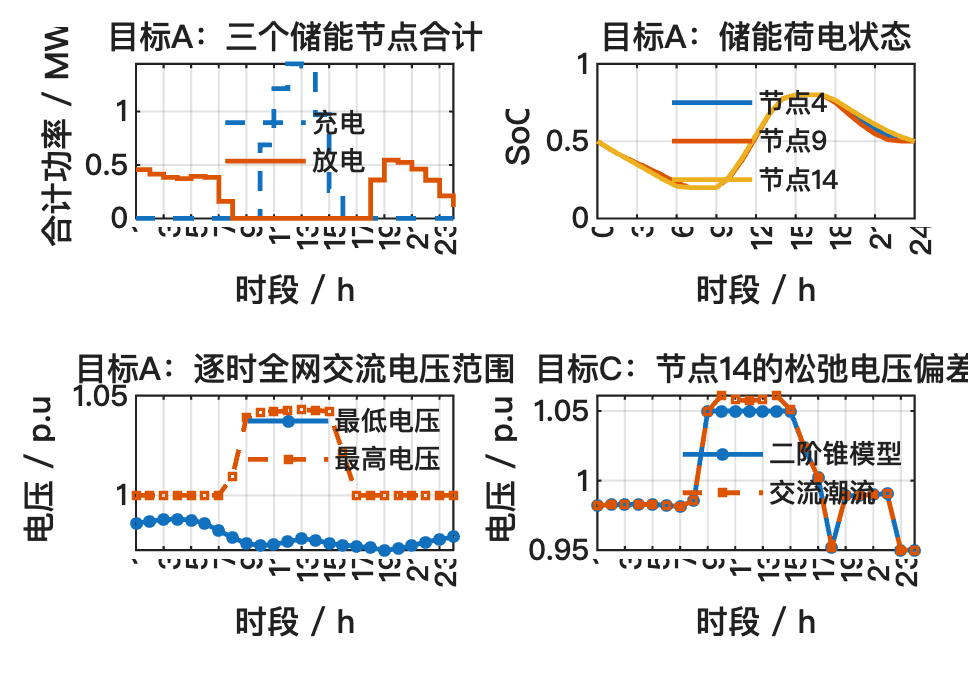

ess_week1_figure(3,struct('Day3',Day3,'Comparison',Comparison),script_dir);

## 保存正式结果

Day3.Comparison = Comparison;
Day3.Completed = true;
Day3.RunTimestamp = char(datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss'));
Day3.IntegerSolutionRecomputed = true;
Day3.CourseCommit = '1d34d745ee234be0d27d8790dc95d687538fab2b';
Day3.SolverNote = local_solver;
save(fullfile(out_dir, 'maoyang_206221321_Day3.mat'), 'Day3', 'Comparison');
summary_file = fullfile(script_dir, 'result_summary.mat');
if isfile(summary_file)
    save(summary_file, 'Day3', '-append');
else
    save(summary_file, 'Day3');
end
fprintf('\n第一周任务三完成，结果已保存到：%s\n', out_dir);


第一周任务三完成，结果已保存到：/Users/apple/Documents/Codex/2026-10-30/meta-lab/outputs/Week1_Final/206221321_maoyang/day3_results


## ======================= 局部函数 =======================

function [Dispatch, SolverName, SolveSeconds, ObjValue] = solve_dispatch(mpc, P, obj_letter, local_solver)
[Dispatch, SolverName, SolveSeconds, ObjValue] = ess_native_dispatch(mpc,P,obj_letter);
end

function [Dispatch, ObjValue] = finish_network(Dispatch, P, obj_letter)
Dispatch.U_bus = voltage_from_flow(Dispatch.P_br, Dispatch.Q_br, Dispatch.L_br, P);
assert(min(Dispatch.U_bus(:)) >= P.V_min^2 - 1e-6 && ...
    max(Dispatch.U_bus(:)) <= P.V_max^2 + 1e-6, ...
    '目标%s模型电压越限 [%.6f, %.6f]。', obj_letter, ...
    sqrt(min(Dispatch.U_bus(:))), sqrt(max(Dispatch.U_bus(:))));
Af_q = sparse(P.fbus, 1:P.N_br, 1, P.N_bus, P.N_br);
At_q = sparse(P.tbus, 1:P.N_br, 1, P.N_bus, P.N_br);
Qres = At_q * (Dispatch.Q_br - diag(P.x_br) * Dispatch.L_br) - Af_q * Dispatch.Q_br;
Dispatch.Q_grid = P.Qd_pu(1, :) - Qres(1, :);
Loss_MWh = P.Sbase * sum(sum(diag(P.r_br) * Dispatch.L_br));
if strcmp(obj_letter, 'C')
    ObjValue = sum((P.Sbase * Dispatch.P_grid') .* P.price_MWh);
else
    ObjValue = Loss_MWh;
end
end

function Data = pack_check_data(Dispatch, mpc, P, Stu_ID, case_name, obj_letter, SolverName, SolveSeconds)
Data = struct('mpc', mpc, 'Stu_ID', Stu_ID, 'case_name', case_name, ...
    'model_type', obj_letter, 'solver', SolverName, 'solve_seconds', SolveSeconds, ...
    'Sbase', P.Sbase, 'dt', P.dt, 'ess_buses', P.ess_buses, 'pv_buses', P.pv_buses, ...
    'PratedMW', 1.5, 'EratedMWh', 3.0, ...
    'SoC0', P.SoC_0, 'SoCmin', P.SoC_min, 'SoCmax', P.SoC_max, ...
    'eta_ch', P.eta_ch, 'eta_dis', P.eta_dis, 'price_MWh', P.price_MWh, ...
    'PloadMW', P.Pd_pu * P.Sbase, 'QloadMvar', P.Qd_pu * P.Sbase, ...
    'PpvMW', P.Sbase * Dispatch.P_pv, 'PpvMaxMW', P.P_pv_max_pu * P.Sbase, ...
    'PchMW', P.Sbase * Dispatch.P_ch, 'PdisMW', P.Sbase * Dispatch.P_dis, ...
    'SoC', Dispatch.SoC, 'u', Dispatch.u_ch, 'U', Dispatch.U_bus, ...
    'L', Dispatch.L_br, 'P', Dispatch.P_br, 'Q', Dispatch.Q_br, ...
    'Pgrid', Dispatch.P_grid, 'Qgrid', Dispatch.Q_grid);
end

function export_objective(Dispatch_Data, Dispatch_Check, V_dispatch_ac, gap_matrix, out_dir, objective_value)
model_type = Dispatch_Data.model_type;
objective_dir = fullfile(out_dir, model_type);
if ~isfolder(objective_dir), mkdir(objective_dir); end
Dispatch_Result = table(string(Dispatch_Data.Stu_ID), string(Dispatch_Data.case_name), ...
    string(model_type), string(Dispatch_Data.solver), Dispatch_Check.Curtailment_MWh, ...
    Dispatch_Check.LineLoss_MWh, Dispatch_Check.GridCost_Yuan, Dispatch_Check.MaxConeGap, ...
    Dispatch_Check.MaxSimultaneousPower_MW, Dispatch_Check.MinACVoltage, Dispatch_Check.MaxACVoltage, ...
    'VariableNames', {'StudentID','Case','Objective','Solver','Curtailment_MWh', ...
    'Loss_MWh','GridCost_Yuan','MaxConeGap','SimultaneousPower_MW','MinACVoltage','MaxACVoltage'});
save(fullfile(objective_dir, 'dispatch_result.mat'), 'Dispatch_Data', 'Dispatch_Check', ...
    'V_dispatch_ac', 'Dispatch_Result', 'objective_value');
end

function Tbl = make_hourly_table(Dispatch, Report, P)
T = P.T;
Tbl = table((1:T)', P.price_MWh, P.Sbase * Dispatch.P_ch(1, :)', ...
    P.Sbase * Dispatch.P_dis(1, :)', P.Sbase * (Dispatch.P_dis(1, :) - Dispatch.P_ch(1, :))', ...
    Dispatch.SoC(1, :)', P.Sbase * Dispatch.P_pv(1, :)', P.Sbase * (P.P_pv_max_pu(1, :)' - Dispatch.P_pv(1, :)'), ...
    P.Sbase * Dispatch.P_grid', ...
    'VariableNames', {'Period', 'Price_YuanPerMWh', 'Charge_MW', 'Discharge_MW', ...
    'NetDischarge_MW', 'SoC_Node4', 'PV_MW_Node4', 'Curtail_MW_Node4', 'Pgrid_MW'});
Tbl.Properties.Description = sprintf('目标 %s；弃光 %.4f MWh；网损 %.4f MWh；购电 %.2f 元；锥间隙 %.2e', ...
    Report.Objective, Report.Curtailment_MWh, Report.LineLoss_MWh, Report.GridCost_Yuan, Report.MaxConeGap);
end

function U = voltage_from_flow(Pbr, Qbr, Lbr, P)
NB = P.N_bus; T = P.T;
adj = cell(NB, 1);
for b = 1:P.N_br
    adj{P.fbus(b)}(end+1) = b;
end
U = zeros(NB, T);
U(1, :) = 1.0;
queue = 1; seen = false(NB, 1); seen(1) = true;
while ~isempty(queue)
    i = queue(1); queue(1) = [];
    for b = adj{i}
        j = P.tbus(b);
        if seen(j), continue; end
        seen(j) = true;
        U(j, :) = U(i, :) - 2 * (P.r_br(b) * Pbr(b, :) + P.x_br(b) * Qbr(b, :)) + ...
            (P.r_br(b)^2 + P.x_br(b)^2) * Lbr(b, :);
        queue(end+1) = j;
    end
end
assert(all(seen), '网络不是连通的辐射状结构。');
end